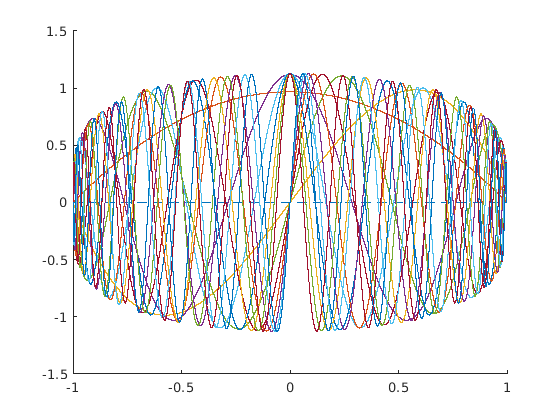

clear all


% Independent parameters
p = 14;  % Size of basis- must be even
r = 1;  % Smoothness of Hilbert space (like the k in H^k)
x_steps = 100000;  % Grid size


% Dependent parameters
order = (1 + r)*p - 2*r - 1;  % Order of polynomial space in the traditional sense
Gegen_Coeffs = zeros(order + 1);  % Power series coeffs for Gegenbauer polynomials, before scaling...
Gegen_Coeffs(1, 1) = 1;
Gegen_Coeffs(2, 2) = 4*r + 1;
for order_ = 2:order
    Gegen_Coeffs(order_ + 1, 1:(order_ + 1)) = ...
          ([0, (2*order_ + 4*r - 1)*Gegen_Coeffs(order_, 1:order_)] ...
        - (order_ + 4*r - 1)*Gegen_Coeffs(order_ - 1, 1:(order_ + 1)))/order_;
end
Ortho_Coeffs = 4^r*gamma(2*r + 1/2)/sqrt(pi)*Gegen_Coeffs;  % ...and after scaling
for order_ = 0:order
    Ortho_Coeffs(order_ + 1, :) = sqrt((order_ + 2*r + 1/2)/prod((1:4*r) + order_))*Ortho_Coeffs(order_ + 1, :);
end


% Get Gegenbauer-like orthogonal polynomials...
Xs = linspace(-1, 1, x_steps + 1);
Orthos = Ortho_Coeffs*(Xs.^((0:order)')).*((1 - Xs.^2).^r);
% ...and their (approximate) derivatives
Ortho_Ds = zeros(order + 1, x_steps + 1);
for i = 2:x_steps
    Ortho_Ds(:, i) = x_steps*(Orthos(:, i + 1) - Orthos(:, i - 1))/4;
end
Ortho_DDs = zeros(order + 1, x_steps + 1);
for i = 2:x_steps
    Ortho_DDs(:, i) = x_steps*(Ortho_Ds(:, i + 1) - Ortho_Ds(:, i - 1))/4;
end
if r == 2
    Ortho_DDs(:, 1)           =   x_steps*Ortho_Ds(:, 2)/2;
    Ortho_DDs(:, x_steps + 1) = - x_steps*Ortho_Ds(:, x_steps)/2;
end


% Assemble the mass/stiffness matrices
M_D  = 2*(Ortho_Ds*Ortho_Ds')/x_steps;
M_DD = 2*(Ortho_DDs*Ortho_DDs')/x_steps;


% Evaluate new FE basis
Coeffs_Even = zeros(p/2, order/2 + 1/2);
Coeffs_Even(1, 1) = 1;
for p_ = 2:(p/2)
    Coeffs_Even_ = Coeffs_Even(1:(p_ - 1), 1:((1 + r)*(p_ - 1) + 1));
    Ps_Even_ = 2*(0:((1 + r)*(p_ - 1))) + 1;
    Coeffs_ = null([ ...
            Coeffs_Even_;
            Coeffs_Even_*M_D(Ps_Even_, Ps_Even_);
            %Coeffs_Even_*M_DD(Ps_Even_, Ps_Even_);
        ]);
    Coeffs_Even(p_, 1:((1 + r)*(p_ - 1) + 1)) = Coeffs_'/norm(Coeffs_);
end

Coeffs_Odd = zeros(p/2, order/2 + 1/2);
Coeffs_Odd(1, 1) = 1;
for p_ = 2:(p/2)
    Coeffs_Odd_ = Coeffs_Odd(1:(p_ - 1), 1:((1 + r)*(p_ - 1) + 1));
    Ps_Odd_ = 2*(0:((1 + r)*(p_ - 1))) + 2;
    Coeffs_ = null([ ...
            Coeffs_Odd_;
            Coeffs_Odd_*M_D(Ps_Odd_, Ps_Odd_);
            %Coeffs_Odd_*M_DD(Ps_Odd_, Ps_Odd_);
        ]);
    Coeffs_Odd(p_, 1:((1 + r)*(p_ - 1) + 1)) = Coeffs_'/norm(Coeffs_);
end

Coeffs = zeros(p, order + 1);
Coeffs(2*(1:(p/2)) - 1, 2*(1:((order + 1)/2)) - 1) = Coeffs_Even;
Coeffs(2*(1:(p/2)),     2*(1:((order + 1)/2))    ) = Coeffs_Odd;


% Plot
clf
hold on
plot(Xs, zeros(size(Xs)), '--')
plot(Xs, Coeffs*Orthos)
hold off

%ylim([-1.5, 1.5])